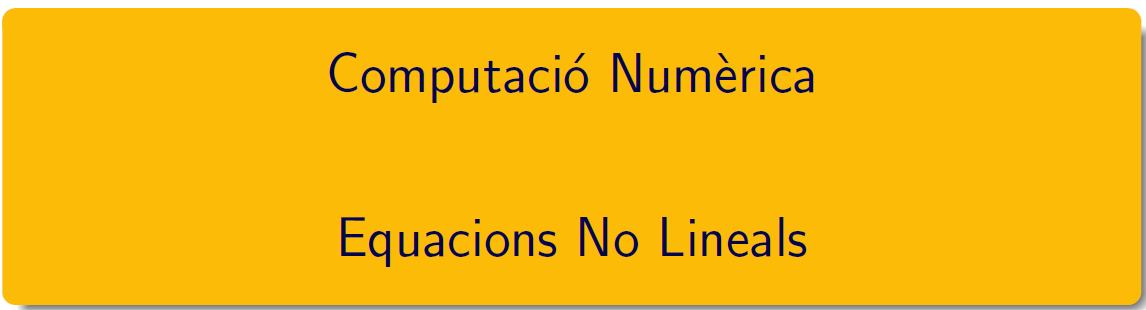

================================================================================

# Pràctica 6. Algorismes clàssics

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab6.pdf i en el document CN_full4.pdf, els podeu trobar en el campus virtual. 

Consulteu els documents [Cleve Moler, Zeroin Algorithms](https://blogs.mathworks.com/cleve/2015/10/12/zeroin-part-1-dekkers-algorithm/)  i el capítol 4 de [Numerical Computing with MATLAB](https://es.mathworks.com/moler/chapters.html), Cleve Moler per a una primera versió dels algorismes de la pràctica.

## 1 Mètode de la bisecció

#### Funció test

Determinar l'arrel real del polinomi $x^3-2x-5 $. Primer de tot localitzem l'arrel

 p = 2;
 q = 5;
 s = sqrt(q^2/4 - p^3/27); %primera part de la fórmula de cardano
 x0 = (q/2 + s)^(1/3) + (q/2 - s)^(1/3) %formula de cardano, és un mètode per

x0 = 2.0946

 % calcular la cúbica en general, i només fa falta resoldre la general per resoldre-les totes!
 f = @(x) x.^3-2*x-5

f = function_handle with value:
    @(x)x.^3-2*x-5


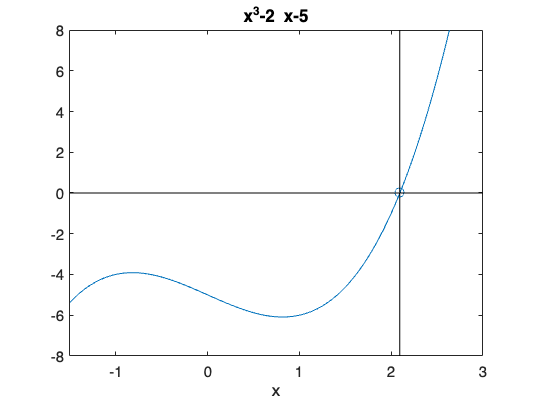

   ezplot(f,[-1.5 3])
   axis([-1.5 3 -8 8])
   line([x0 x0],[0 0],'marker','o')
   line([x0 x0],[-8 8],'color','k')
   line([-1.5 3],[0 0],'color','k')

t = (1:0.25:3)';
disp(table(t,f(t),'VariableNames',{'t','f(t)'}))

     t       f(t)  
    ____    _______

       1         -6
    1.25    -5.5469
     1.5     -4.625
    1.75    -3.1406
       2         -1
    2.25     1.8906
     2.5      5.625
    2.75     10.297
       3         16



#### Pràctiquem.... Algorisme

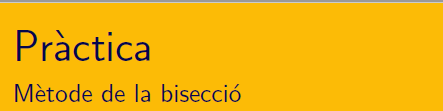

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la bisecció. Els arguments d'entrada han de ser l'interval inicial $$[a,b]$$i la funció $$f$$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el punt mig $$\alpha_{n+1}$$ i els valors de la funció per observar l'acompliment dels criteris d'aturada.

a = 2

a = 2

b = 2.25

b = 2.2500

f = @(x) x.^3-2*x-5

f = function_handle with value:
    @(x)x.^3-2*x-5


arrelAprox = bisect(f,a,b)

    1   2.000000000000000  -1.000000000000000
    2   2.250000000000000   1.890625000000000
    3   2.125000000000000   0.345703125000000
    4   2.062500000000000  -0.351318359375000
    5   2.093750000000000  -0.008941650390625
    6   2.109375000000000   0.166835784912109
    7   2.101562500000000   0.078562259674072
    8   2.097656250000000   0.034714281558990
    9   2.095703125000000   0.012862332165241
   10   2.094726562500000   0.001954347826540
   11   2.094238281250000  -0.003495149197988
   12   2.094482421875000  -0.000770775208366
   13   2.094604492187500   0.000591692672970
   14   2.094543457031250  -0.000089564676045
   15   2.094573974609375   0.000251058146290
   16   2.094558715820312   0.000080745272090
   17   2.094551086425781  -0.000004410067735
   18   2.094554901123047   0.000038167510738
   19   2.094552993774414   0.000016878698641
   20   2.094552040100098   0.000006234309739
   21   2.094551563262939   0.000000912119573
   22   2.094551324844360  -0.0000

arrel = 2.0946

## 2 Mètode de la tangent

#### Funció test

Determinar l'arrel real del polinomi $x^3-2x-5 $. Primer de tot localitzem l'arrel

#### Pràctiquem.... Algorisme

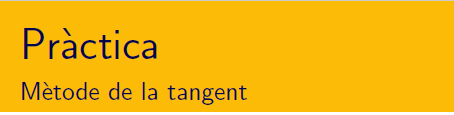

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la tangent. Els arguments d'entrada han de ser lel valor inicial $x_0$ i les funcions $$f$$i $f^\prime$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el valor calculat $$x_{n+1}$$ i els valors de la funció per observar l'acompliment dels criteris d'aturada.

f = @(x) x.^3-2*x-5

f = function_handle with value:
    @(x)x.^3-2*x-5


fprime = @(x) 3*x.^2-2

fprime = function_handle with value:
    @(x)3*x.^2-2


a = 2;
disp(a)

     2



arrelAprox = newton(f,fprime,a)

    0    2.000000000000000000  -1.000000000000000e+00
    2    2.100000000000000089   6.100000000000083e-02
    3    2.094568121104185110   1.857231732707021e-04
    4    2.094551481698199158   1.739761223973346e-09
    5    2.094551481542326510  -8.881784197001252e-16
    6    2.094551481542326510  -8.881784197001252e-16


arrelAprox = 2.0946

%    z = 0;
%    while abs(x-z) > eps(x)
%       z = x;
%       x = x - f(x)/fprime(x);
%       disp(x)
%    end
% xn = newton(f,fp,a,maxIt,tol)

## 3 Mètode de la secant

#### Funció test

Determinar l'arrel real del polinomi $x^3-2x-5 $. Primer de tot localitzem l'arrel

f = @(x) x.^3-2*x-5

f = function_handle with value:
    @(x)x.^3-2*x-5


a=2; b=2.1; 
f = @(x) x.^3-2*x-5

f = function_handle with value:
    @(x)x.^3-2*x-5


a=2; b=2.1; 
arrelAproximada = secant(f,a,b)

    1   2.000000000000000  -1.000000000000000e+00
    2   2.100000000000000   6.100000000000083e-02
    3   2.094250706880302  -3.356509233812588e-03
    4   2.094550560860480  -1.027612776827169e-05
    5   2.094551481698244   1.740267485672575e-09
    6   2.094551481542327  -8.881784197001252e-16
    7   2.094551481542327  -8.881784197001252e-16


arrelAproximada = 2.0946

% xs = secant(f,a,b,maxIt,tol)

#### Pràctiquem.... Algorisme

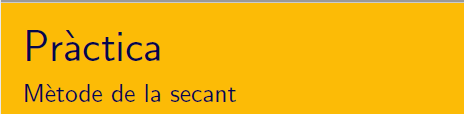

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la secant. Els arguments d'entrada han de ser els valors inicials $x_1$ i $x_2$ i  la funció $$f$$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el valor calculat $$x_{n+1}$$ i els valors de la funció pels valors de la funció per observar l'acompliment dels criteris d'aturada.

f = @(x) x.^3-2*x-5

f = function_handle with value:
    @(x)x.^3-2*x-5


a=2; b=2.1;
z = zeroin(f,-10,10)

    1  initial -10.000000000000000  -9.850000000000000e+02
    2  initial  10.000000000000000   9.750000000000000e+02
    3  secant    0.051020408163266  -5.101908006017903e+00
    4  secant    0.102809694784050  -5.204532708228332e+00
    5  bisect    5.051404847392025   1.137923265698163e+02
    6  secant    0.319245031714663  -5.605953442938869e+00
    7  bisect    2.685324939553344   8.993147783474912e+00
    8  secant    1.227803277863287  -5.604692022668690e+00
    9  bisect    1.956564108708316  -1.423120802484996e+00
   10  secant    2.204584444558592   1.305536055296063e+00
   11  secant    2.085918189409717  -9.589225176130167e-02
   12  secant    2.094037887261547  -5.730793220462438e-03
   13  secant    2.094553987046916   2.796507289026806e-05
   14  secant    2.094551480817728  -8.087558178715426e-09
   15  secant    2.094551481542326  -1.154631945610163e-14
   16  secant    2.094551481542327  -8.881784197001252e-16
   17  minimal   2.094551481542327   3.552713678800501e-

z = 2.0946


fzero(f,0)

ans = 2.0946

f=@(x)1./(x-3)-6

f = function_handle with value:
    @(x)1./(x-3)-6


options = optimset('Display','iter'); % show iterations
[x fval exitflag output] = fzero(f,4,options)

 
Search for an interval around 4 containing a sign change:
 Func-count    a          f(a)             b          f(b)        Procedure
    1               4            -5             4            -5   initial interval
    3         3.88686      -4.87243       4.11314      -5.10164   search
    5            3.84      -4.80952          4.16      -5.13793   search
    7         3.77373      -4.70755       4.22627      -5.18452   search
    9            3.68      -4.52941          4.32      -5.24242   search
   11         3.54745      -4.17335       4.45255      -5.31155   search
   13            3.36      -3.22222          4.64      -5.39024   search
   14          3.0949       4.53704          4.64      -5.39024   search
 
Search for a zero in the interval [3.0949, 4.64]:
 Func-count    x          f(x)             Procedure
   14          3.0949       4.53704        initial
   15          3.0949       4.53704        interpolation
   16         3.43982      -3.72635        interpolation


x = 3.1667

fval = 5.3291e-15

exitflag = 1

output = struct with fields:
    intervaliterations: 7
            iterations: 11
             funcCount: 25
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [3.0949, 4.64]'


% xs = secant(f,a,b,maxIt,tol)

## 4. Mètode de la iteració simple 

#### Funcions test

Per a resoldre $x^3=2x+5$  es proposen els mètodes


$$
\mathbf{(f1)}~x_{n+1} = \frac12(x_n^3-5)\,,\qquad \mathbf{(f2)}~x_{n+1} = \sqrt[3]{2x_n+5}\,,$$
 

Construïm les funcions per generar els mètodes iteratius.

#### Pràctiquem.... Algorisme

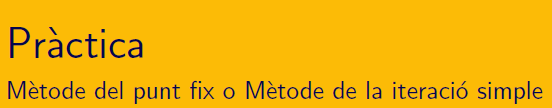

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la iteració simple. Els arguments d'entrada han de ser el valor inicials $x_1$, la funció $$f$$i la funció $g$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el valor calculat $$x_{n+1}$$ i els valors de la funció  per observar l'acompliment dels criteris d'aturada.

#### Pràctiquem.... Teorema de convergència

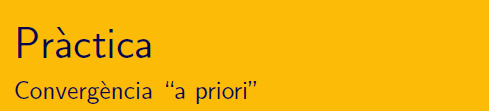

Escriure un `live script de MATLAB® `que:

- analitzi la convergència "a priori" del mètode de la iteració simple $x_{n+1} = g(x_n)$ consistent per a l'equació $f(x)=0$ i obtingui l'interval maximal de convergència en funció de la condició inicial $x_0$

- obtenir el nombre d'iteracions necessàries per acomplit el criteri d'aturada  $tol_x <\epsilon$

clear x
g1 = @(x)1/2*(x.^3-5)

g1 = function_handle with value:
    @(x)1/2*(x.^3-5)


g2 = @(x)nthroot(2*x+5,3)

g2 = function_handle with value:
    @(x)nthroot(2*x+5,3)



dg1 = @(x)3*x.^2/2

dg1 = function_handle with value:
    @(x)3*x.^2/2


dg2 = @(x)2/3*nthroot((2*x+5),-3)

dg2 = function_handle with value:
    @(x)2/3*nthroot((2*x+5),-3)


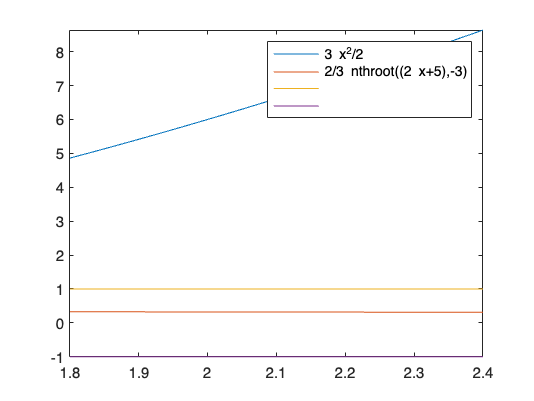


% t=linspace(1.8,2.4);
fplot({dg1,dg2,1,-1},[1.8,2.4]),legend('show')

function b = bisect(f,a,b)
   s = '%5.0f %19.15f %19.15f\n';
   fprintf(s,1,a,f(a))
   fprintf(s,2,b,f(b))
   k = 2;
   while abs(b-a) > eps(abs(b))
      x = (a + b)/2;
      if sign(f(x)) == sign(f(b))
         b = x;
      else 
         a = x;
      end
      k = k+1;
      fprintf(s,k,x,f(x))
   end
end
%-----------------------------
function b = secant(f,a,b)
   s = '%5.0f %19.15f %23.15e\n';
   fprintf(s,1,a,f(a))
   fprintf(s,2,b,f(b))
   k = 2;
   while abs(b-a) > eps(abs(b))
      c = a;
      a = b;
      b = b + (b - c)/(f(c)/f(b) - 1);
      k = k+1;
      fprintf(s,k,b,f(b))
   end
end
%-----------------------------
function x = newton(f,fprime,x)
   s = '%5.0f %23.18f %23.15e\n';
   fprintf(s,0,x,f(x))
   k = 1;
   z = 0;
   while abs(x-z) > eps(x)
      z = x;
      x = x - f(x)/fprime(x);
      k = k+1;
      fprintf(s,k,x,f(x))
   end
end
%---------
function b = zeroin(f,a,b)
   % Zeroin(f,a,b) reduces the interval [a,b] to a tiny
   % interal on which the function f(x) changes sign.
   % Returns one end point of that interval.

   fa = f(a);
   fb = f(b);
   if sign(fa) == sign(fb)
      error('Sorry, f(x) must change sign on the interval [a,b].')
   end
   s = '%5.0f %8s %19.15f %23.15e\n';
   fprintf(s,1,'initial',a,fa)
   fprintf(s,2,'initial',b,fb)
   k = 2;

   % a is the previous value of b and [b, c] always contains the zero.
   c = a; fc = fa;
   while true
      if sign(fb) == sign(fc)
         c = a; fc = fa;
      end

      % Swap to insure f(b) is the smallest value so far.
      if abs(fc) < abs(fb)
         a = b; fa = fb;
         b = c; fb = fc;
         c = a; fc = fa;
      end

      % Midpoint.
      m = (b + c)/2;
      if abs(m - b) <= eps(abs(b))
         return   % Exit from the loop and the function here.
      end

      % p/q is the the secant step.
      p = (b - a)*fb;
      if p >= 0
         q = fa - fb;
      else
         q = fb - fa;
         p = -p;
      end
      % Save this point.
      a = b; fa = fb;
      k = k+1;

      % Choose next point.
      if p <= eps(q)
         % Minimal step.
         b = b + sign(c-b)*eps(b);
         fb = f(b);
         fprintf(s,k,'minimal',b,fb)

      elseif p <= (m - b)*q
         % Secant.
         b = b + p/q;
         fb = f(b);
         fprintf(s,k,'secant ',b,fb)

      else
         % Bisection.
         b = m;
         fb = f(b);
         fprintf(s,k,'bisect ',b,fb)
      end
   end
end